# Cvičení 9 - B2M31AEDA

## Nahrání dat

**Popis dat:** Pracovní data jsou uložena v souboru data.csv, který je k dispozici ke stažení na Moodle stránce tohoto předmětu, ve složce příslušného cvičení. Pro načtení dat do Matlabu využijte funkce `readtable`*.*

close all; clear; clc; addpath(genpath(fullfile([pwd '\Uni' '\grad' '\AEDA' '\week09' '\sem'])))
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";
T = readtable('data.csv', 'ReadVariableNames', true);
classification = ismember(T.group, 'PD');
HC = T(~classification, :);
PD = T(classification, :);

## 1. Vizualizace 

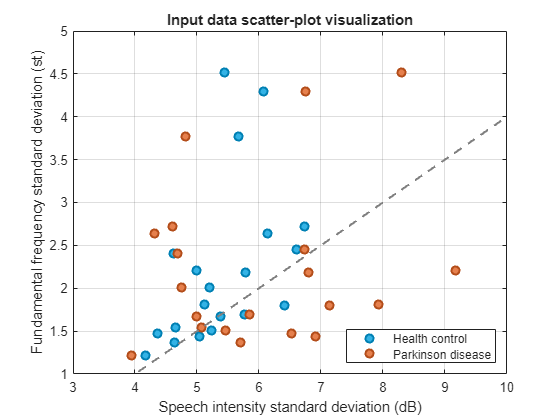

figure
plot(HC.stdPWR, HC.stdF0, 'o', 'MarkerEdgeColor', [.0 .5 .7], 'MarkerFaceColor', [.2 .7 .9], 'LineWidth', 1.5)
hold on
plot(PD.stdPWR, HC.stdF0, 'o', 'MarkerEdgeColor', [.7 .3 .1], 'MarkerFaceColor', [.9 .5 .3], 'LineWidth', 1.5)

ax = axis;
xx = [ax(1), ax(2)];
plot(xx, 0.5*(xx-4)+1, '--', 'LineWidth', 1.5, 'Color', [.5 .5 .5])
xlim([ax(1), ax(2)])
ylim([ax(3), ax(4)])

hold off
grid on
xlabel('Speech intensity standard deviation (dB)')
ylabel('Fundamental frequency standard deviation (st)')
legend('Health control', 'Parkinson disease', 'Location', 'southeast')
title('Input data scatter-plot visualization')

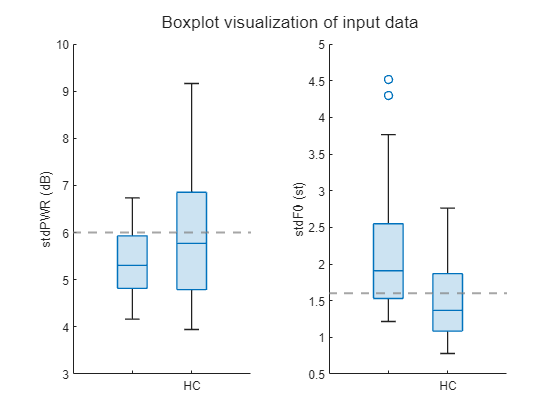

figure
tiles = tiledlayout(1,2);
nexttile
boxchart(categorical(classification), [HC.stdPWR; PD.stdPWR])
hold on
yline(6, '--', 'LineWidth', 1.5, 'Color', [.5 .5 .5])
hold off
xticklabels(["", "HC", "", "PD"])
ylabel('stdPWR (dB)')

nexttile
boxchart(categorical(classification), [HC.stdF0; PD.stdF0])
hold on
yline(1.6, '--', 'LineWidth', 1.5, 'Color', [.5 .5 .5])
hold off
xticklabels(["", "HC", "", "PD"])
ylabel('stdF0 (st)')

title(tiles, 'Boxplot visualization of input data')

### **Otázky:**

- Pohledem na vaší vizualizaci zhodnoťte, jak dobře lze oddělit skupiny v 2D prostoru pomocí lineární rozhodovací hranice. Do vizualizace můžete zakreslit (od ruky) kam byste rozhodovací hranici umístili.

- Zhodnoťte, zda není pro klasifikaci některý z parametrů nadbytečný, a zvažte, jak by se obecně daly nadbytečné (redundantní) parametry automaticky identifikovat ve vícedimenzionálních datasetech.

### **Odpovědi:**

- Ze scatter plotu je vidět, že lineární rozhodovací hranice nebude postačující, neboť data jsou příliš "namíchána", a tak se lineární hranice težko kreslí. Ve vizualizaci pomocí boxplotů jsme schopni učinit alespoň odhad, kde by se 1D lineární hranice pro jednotlivé parametry daly nakreslit.

- Aby byl některý z parametrů pro klasifikaci přímo nadbytečný, musel by se jeho boxplot pro jednotlivé skupiny značně překrývat. Takto můžeme posuzovat redundanci jednotlivých parametrů i v případě, že pracujeme s vícedimenzionálními datasety, kde se delá hromadná vizualizace špatně. K překrývání v našem případě sice dochází, zejména v případě parametru stdPWR, ale parametr přesto nevyloučíme, neboť tam alespoň nějaká variance je.

## 2. Klasifikace dat

Proveďte klasifikaci dat pomocí následujících metod a pro každou z nich vykreslete do obrázku s daty příslušnou rozhodovací hranici (decision boundary), abyste je mohli mezi sebou snadno vizuálně porovnat:

**1. Logistická regrese (Logistic regression)**

- Použijte funkce `glmfit` a `glmval`, se standardním nastavením pro binomiální rozdělení výstupní funkce.

- Pro vykreslení rozhodovací hranice můžete použít funkci `contour` na úrovni 0.5.

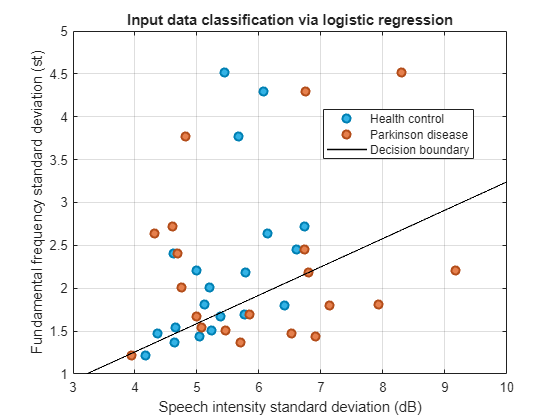

tic;
LRparameters = glmfit([T.stdPWR, T.stdF0], classification, 'binomial', 'Link', 'logit');
LRclassification = glmval(LRparameters, [T.stdPWR, T.stdF0], 'logit') >= .5;
LRtime = sprintf("%.2f ms", toc*1e3);
LRaccuracy = sprintf("%.1f %%", sum(LRclassification==classification)/length(classification)*100);

figure
plot(HC.stdPWR, HC.stdF0, 'o', 'MarkerEdgeColor', [.0 .5 .7], 'MarkerFaceColor', [.2 .7 .9], 'LineWidth', 1.5)
hold on
plot(PD.stdPWR, HC.stdF0, 'o', 'MarkerEdgeColor', [.7 .3 .1], 'MarkerFaceColor', [.9 .5 .3], 'LineWidth', 1.5)

% Extrapolate the axes (predictor ranges) to classify NxN displayed gridpoints
N = 1000;
ax = axis;
xx = linspace(ax(1), ax(2), N);
yy = linspace(ax(3), ax(4), N);
[X, Y] = meshgrid(xx, yy);
XYgrid = [X(:), Y(:)];
LRgrid = glmval(LRparameters, XYgrid, 'logit');
LRgrid = reshape(LRgrid, size(X));
% Plot the 0.5 contour as the HC:PD ~ 50:50 boundary (LR decision boundary)
contour(xx, yy, LRgrid, [.5 .5], 'LineWidth', 1', 'LineColor', 'k', 'ShowText', false)

hold off
grid on
xlabel('Speech intensity standard deviation (dB)')
ylabel('Fundamental frequency standard deviation (st)')
legend('Health control', 'Parkinson disease', 'Decision boundary', 'Location', 'best')
title('Input data classification via logistic regression')

**2. Lineární diskriminantní analýza (LDA)**

- Pro výpočet modelu použijte funkci `fitdiscr`.

- Klasifikaci původních dat můžete provést použitím funkce `predict`.

- Rozhodovací hranici vykreslete za použití koeficientů z vypočteného modelu.

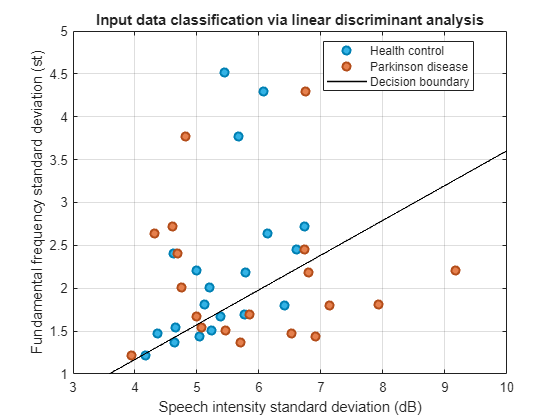

tic
LDAmodel = fitcdiscr([T.stdPWR, T.stdF0], classification);
LDAclassification = predict(LDAmodel, [T.stdPWR, T.stdF0]) >= .5;
LDAtime = sprintf("%.2f ms", toc*1e3);
LDAaccuracy = sprintf("%.1f %%", sum(LDAclassification==classification)/length(classification)*100);

figure
plot(HC.stdPWR, HC.stdF0, 'o', 'MarkerEdgeColor', [.0 .5 .7], 'MarkerFaceColor', [.2 .7 .9], 'LineWidth', 1.5)
hold on
plot(PD.stdPWR, HC.stdF0, 'o', 'MarkerEdgeColor', [.7 .3 .1], 'MarkerFaceColor', [.9 .5 .3], 'LineWidth', 1.5)

% Extrapolate the axes (predictor ranges) to classify NxN displayed gridpoints
N = 1000;
ax = axis;
xx = linspace(ax(1), ax(2), N);
yy = linspace(ax(3), ax(4), N);
[X, Y] = meshgrid(xx, yy);
XYgrid = [X(:), Y(:)];
LDAgrid = predict(LDAmodel, XYgrid);
LDAgrid = reshape(LDAgrid, size(X));
% Plot the 0.5 contour as the HC:PD ~ 50:50 boundary (LDA decision boundary)
contour(xx, yy, LDAgrid, [.5 .5], 'LineWidth', 1', 'LineColor', 'k', 'ShowText', false)

hold off
grid on
xlabel('Speech intensity standard deviation (dB)')
ylabel('Fundamental frequency standard deviation (st)')
legend('Health control', 'Parkinson disease', 'Decision boundary', 'Location', 'best')
title('Input data classification via linear discriminant analysis')

**3. Support Vector Machine (SVM) s lineárním jádrem**

- Výpočet modelu proveďte využitím funkce `fitcsvm`.

- Pokud chcete, můžete si vykreslit vhodným způsobem do obrázku jaké datové body použil model jako *Support Vectors*.

- Koeficienty pro vykreslení rozhodovací hranice SVM modelu získáte z Matlabovské proměnné (*structure*) modelu (pole `Beta` a `Bias`).

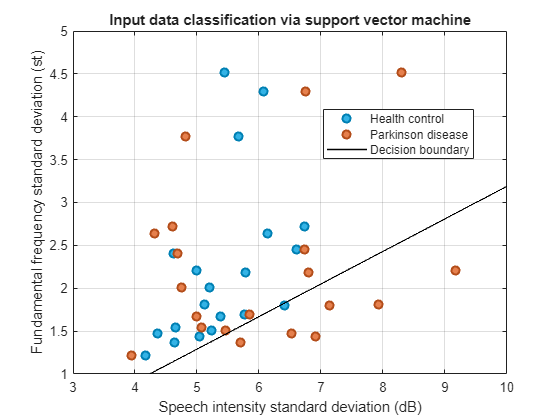

tic
SVMmodel = fitcsvm([T.stdPWR, T.stdF0], classification);
SVMclassification = predict(SVMmodel, [T.stdPWR, T.stdF0]) >= .5;
SVMtime = sprintf("%.2f ms", toc*1e3);
SVMaccuracy = sprintf("%.1f %%", sum(SVMclassification==classification)/length(classification)*100);

figure
plot(HC.stdPWR, HC.stdF0, 'o', 'MarkerEdgeColor', [.0 .5 .7], 'MarkerFaceColor', [.2 .7 .9], 'LineWidth', 1.5)
hold on
plot(PD.stdPWR, HC.stdF0, 'o', 'MarkerEdgeColor', [.7 .3 .1], 'MarkerFaceColor', [.9 .5 .3], 'LineWidth', 1.5)

% Extrapolate the axes (predictor ranges) to classify NxN displayed gridpoints
N = 1000;
ax = axis;
xx = linspace(ax(1), ax(2), N);
yy = linspace(ax(3), ax(4), N);
[X, Y] = meshgrid(xx, yy);
XYgrid = [X(:), Y(:)];
SVMgrid = predict(SVMmodel, XYgrid);
SVMgrid = reshape(SVMgrid, size(X));
% Plot the 0.5 contour as the HC:PD ~ 50:50 boundary (SVM decision boundary)
contour(xx, yy, SVMgrid, [.5 .5], 'LineWidth', 1', 'LineColor', 'k', 'ShowText', false)

hold off
grid on
xlabel('Speech intensity standard deviation (dB)')
ylabel('Fundamental frequency standard deviation (st)')
legend('Health control', 'Parkinson disease', 'Decision boundary', 'Location', 'best')
title('Input data classification via support vector machine')

## 3. Porovnání klasifikací

Porovnejte jednotlivé klasifikátory z hlediska výpočetní náročnosti a přesnosti klasifikace.

- Pro měření výpočetní náročnosti využijte časoměrné funkce `tic` a `toc`.

- Pro každý z klasifikátorů vypočtěte a zobrazte matici záměn (*Confusion** matrix*) – využijte funkcí `confusionmat`, resp. `confusionchart`. Přesnost klasifikace určete jako procento dat, které by model přiřadil do správné skupiny.

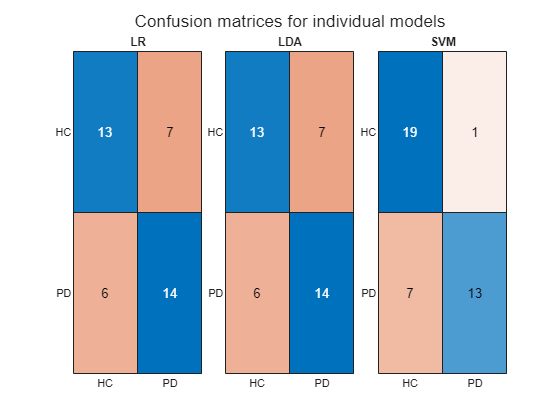

LRconfusionMatrix = confusionmat(classification, LRclassification);
LDAconfusionMatrix = confusionmat(classification, LDAclassification);
SVMconfusionMatrix = confusionmat(classification, SVMclassification);

figure
tiles = tiledlayout('horizontal', 'TileSpacing', 'compact');
nexttile; confusionchart(LRconfusionMatrix, {'HC', 'PD'}, 'XLabel', [], 'YLabel', []); title('LR')
nexttile; confusionchart(LDAconfusionMatrix, {'HC', 'PD'}, 'XLabel', [], 'YLabel', []); title('LDA')
nexttile; confusionchart(SVMconfusionMatrix, {'HC', 'PD'}, 'XLabel', [], 'YLabel', []); title('SVM')
title(tiles, 'Confusion matrices for individual models')

### **Délky výpočtů a procentuální přesnost klasifikace (pro všechny modely):**

results = array2table([[LRaccuracy; LDAaccuracy; SVMaccuracy], [LRtime; LDAtime; SVMtime]], ...
    "RowNames", ["LR", "LDA", "SVM"], ...
    "VariableNames", ["Accuracy", "Time"]);
disp(results)

           Accuracy       Time    
           ________    ___________

    LR     "67.5 %"    "128.36 ms"
    LDA    "67.5 %"    "426.28 ms"
    SVM    "80.0 %"    "256.11 ms"



### **Zhodnocení a porovnání modelů:**

- Z hlediska přesnosti: Modely LR a LDA sdílí stejné skóre přesnosti, zatímco model SVM dosahuje přesnosti výrazně vyšší.

- Z hlediska výpočetní náročnosti: Jako zdaleka nejlepší se jeví LR, následuje o něco pomalejší SVM a nakonec LDA s o poznání horším časem.

- Souhrnně: Jako nejvhodnější model pro nás dataset volíme SVM, který jako jediný dosahuje přijatelné přesnosti za cenu zpoždění oproti nejrychlejšímu výpočtu pomoci LR. Toto zpoždění je však stále výrazně nižší než v případě LDA.

## Nepovinný bonus:

Implementujte manuálně algoritmus pro výpočet lineární diskriminační analýzy LDA. Pro otestování funkce použijte data uložená v souboru bonus.csv, který je dostupný ke stažení na Moodlu (proměnné jsou značeny x a y).

Odevzdejte včetně grafického zobrazení dat a rozhodovací hranice.

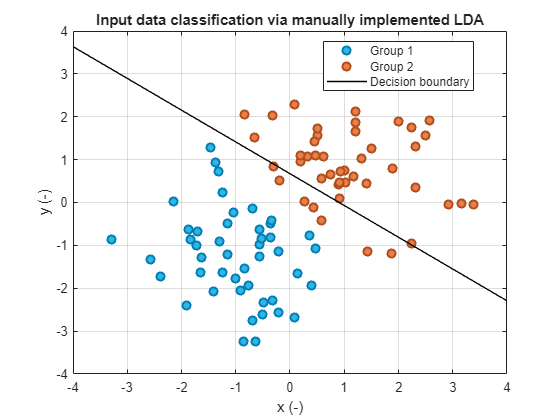

T = readtable('bonus.csv', 'ReadVariableNames', true);
classification = ismember(T.group, 2);
group1 = [T.x(~classification), T.y(~classification)]';
group2 = [T.x(classification), T.y(classification)]';

mean1 = mean(group1, 2);
mean2 = mean(group2, 2);
S1 = (group1(1:end,:)-mean1)*(group1(1:end,:)-mean1)';
S2 = (group2(1:end,:)-mean2)*(group2(1:end,:)-mean2)';

Sw = S1 + S2;
Sb = (mean1-mean2)*(mean1-mean2)';
[V, D] = eig(Sw\Sb);
[~, idx] = max([D(1,1), D(2,2)]);
w = V(:,idx);


figure
plot(group1(1,:), group1(2,:), 'o', 'MarkerEdgeColor', [.0 .5 .7], 'MarkerFaceColor', [.2 .7 .9], 'LineWidth', 1.5)
hold on
plot(group2(1,:), group2(2,:), 'o', 'MarkerEdgeColor', [.7 .3 .1], 'MarkerFaceColor', [.9 .5 .3], 'LineWidth', 1.5)

ax = axis;
xx = [ax(1), ax(2)];
plot(xx, -w(1)*xx + w(2), 'LineWidth', 1', 'Color', 'k')

hold off
grid on
xlabel('x (-)')
ylabel('y (-)')
legend('Group 1', 'Group 2', 'Decision boundary', 'Location', 'best')
title('Input data classification via manually implemented LDA')